# 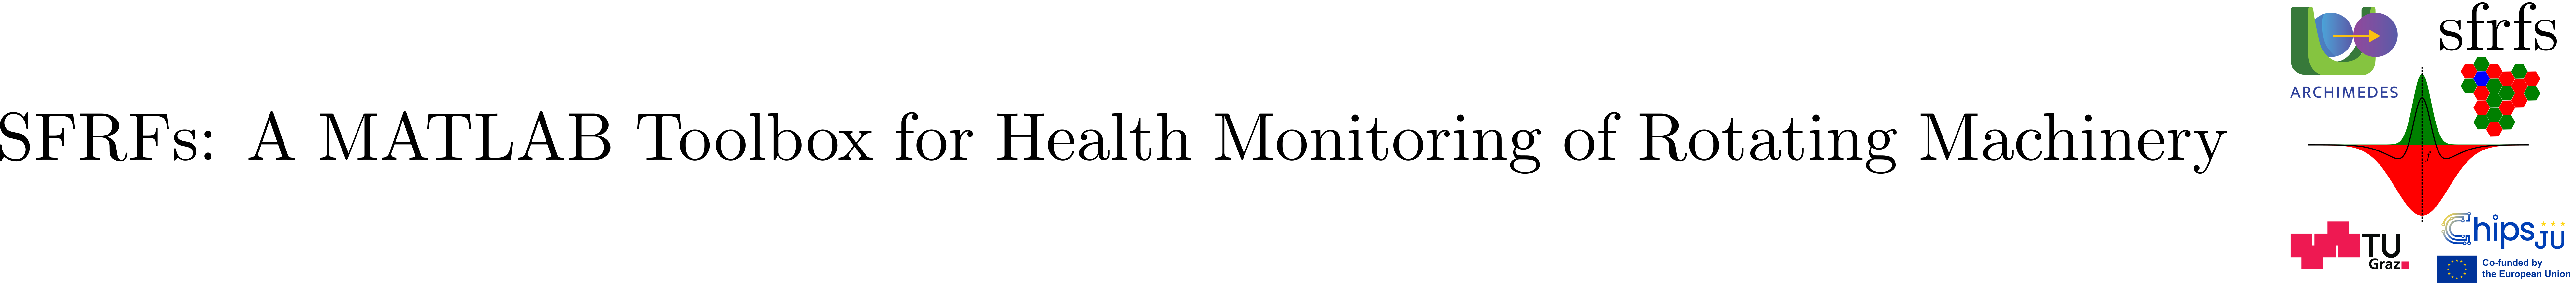

# SFRFs toolbox description

## Introduction

The **Spectral Faults Receptive Fields (SFRFs) toolbox** implements the computation of **condition indicators (CIs)** by monitoring characteristic fault frequencies. This is achieved by defining Gaussian frequency filters centered on the fault characteristic frequencies and computing a local frequency contrast. Contrast computation requires specifying bandwidths both for the fault frequencies of interest and for their surrounding context. 

Inspired by the receptive fields of retinal ganglion cells in the primate retina, the Gaussian filters centered on the fault frequencies are referred to as the "center", while the broader filter capturing the local context is referred to as the "surround".

The toolbox is implemented using object-oriented programming and leverages MATLAB’s advanced capabilities for data handling, signal processing, and parallel computing. In the following sections, we present the conceptual framework and illustrate its usage through a running example.

## Running Example

We will illustrate SFRFs using the  Wang et al.'s [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) rolling bearing run-to-failure dataset.

### Snapshot parameters

In rotating machinery vibration analysis is a well stablished field to assess the state of health of machines. Vibrations as measured via digital accelerometers will be the raw input data to our toolbox. Our toolbox defines the class [ParametersSnapshot](matlab:open('./api/ParametersSnapshot.mlx')) to carry the parameters of the digital signal. 

We create the snapshot parameters object corresponding to  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset.

% Creates the descriptor for signal snapshots of XJTU-SY dataset
sp = ParametersSnapshot(...
        'samplingFrequency', 25600, ...
        'duration', 1.28, ...
        'stride', 60)

sp =   ParametersSnapshot with properties:

    samplingFrequency: 25600
             duration: 1.2800
               stride: 60


### Operating conditions

For [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset operating conditions are specified by rotor speed and load. SFRFs toolbox defines the class [OperatingConditions](matlab:open('./api/OperatingConditions.mlx')) to represent such parameters. 

% define vector of rotor speeds
speeds = [35; 37.5; 40];
% define vector with system loads
loads  = [12; 11; 10];
% create the operating conditions
oc = OperatingConditions(speeds, loads);
% displaying internal table
disp(oc.conditionsTable);

    Speed    Load
    _____    ____

      35      12 
    37.5      11 
      40      10 



### Bearing parameters

Geometric parameters for rolling bearings can be specified in the class [ParametersRollingBearings](matlab:open('../ParametersRollingBearings.m')). Detailed documentation for the class can be found [here](matlab:open('./api/ParametersRollingBearings.mlx')).

% create the parameters for the bearing
bp = ParametersRollingBearings( ...
            'numRollingElements',8, ...
            'ballDiameter',7.92, ...
            'pitchDiameter',34.55, ...
            'contactAngle',0)

bp =   ParametersRollingBearings with properties:

    numRollingElements: 8
          ballDiameter: 7.9200
         pitchDiameter: 34.5500
          contactAngle: 0


## XJTU-SY dataset

### Dataset preparation

To be able to run the examples in this notebook please follow the steps below:

- Choose or create a folder on your computer to store the dataset.

- Download the dataset `.zip` file from one of the official repositories specified in the github project: [XJTU-SY Bearing Dataset](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets?utm_source=chatgpt.com)

- Unzip the dataset into your chosen folder.

- Verify that the unzipped folder contains subfolders for each bearing and operating condition.

### Dataset file organization

Knowing the root folder is important to the processing pipeline, The structure of the dataset starting in the root folder is shown in Table 1.

**Table 1**. File organization of  [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) dataset.

### Ensemble creation

To work with [**XJTU-SY**](https://github.com/WangBiaoXJTU/xjtu-sy-bearing-datasets) run-to-failure bearing dataset we first transform it into a MATLAB [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) compatible with the [Predictive Maintenance Toolbox](https://www.mathworks.com/products/predictive-maintenance.html). In the resulting ensemble, each member corresponds to a bearing and contains all signal snapshots recorded during its operational life.

Create a fileEnsembleDatastore for the XJTU-SY using the utility function [createXJTUSYEnsemble](matlab:open('./api/createXJTUSYEnsemble.mlx')). 

After creation, a set of matlab files will be produced as shown in Figure 1.

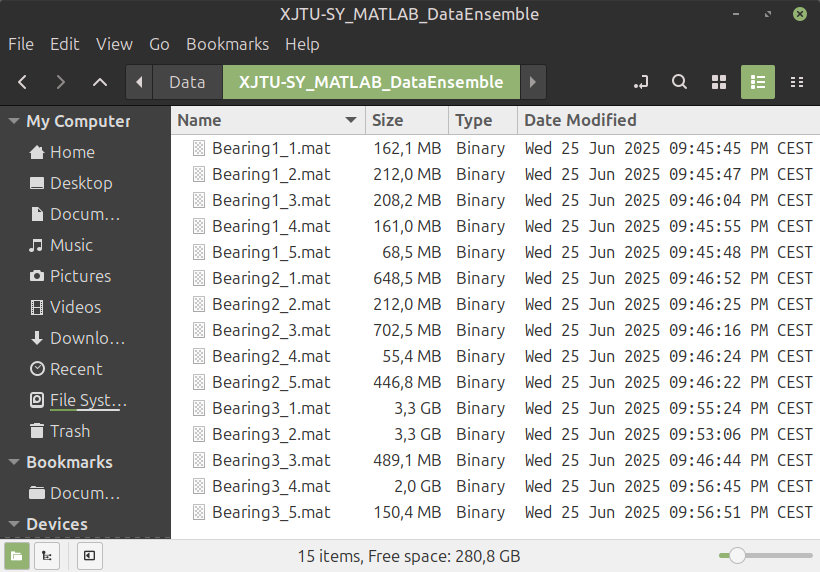

**Figure 1**. MATLAB ensemble for XJTU-SY.

### Ensemble fields

The resulting ensemble contains the following fields:

- `Label`: identifier of the bearing

- `SnapshotIndex`: index of the snapshot (see [ParametersSnapshot](matlab:open('./ParametersSnapshot.mlx'))). This integer sorts the snapshots chronologically.

- `HorizontalAcceleration` and `VerticalAcceleration `(see [ParametersSnapshot](matlab:open('./ParametersSnapshot.mlx'))): raw vibration signals, each as a 32768×1 double array

- `Speed` and `Load`: operating conditions (see [OperatingConditions](matlab:open('./OperatingConditions.mlx')))

- `Lifetime`: total number of snapshots until failure (in this case minutes)

### Create an ensemble handle

After the conversion  [createXJTUSYEnsemble](matlab:open('./api/createXJTUSYEnsemble.mlx')) function will return a [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle. Creating the ensemble is generally costly and should be performed only once. The function [getXJTUSYEnsemble](matlab:open('./api/getXJTUSYEnsemble.mlx')) allows us to create a handle to the ensemble without repeating the transformation step. Since the MATLAB files backing the ensemble have already been created, we use this function to obtain the handle efficiently.

% Obtain a handle to an existing ensemble by selecting its folder via GUI.
% This creates a configured fileEnsembleDatastore without loading any data.
ensemble = data.getXJTUSYEnsemble();

% print a summary of members
firstMember = read(ensemble);
summary(firstMember)


firstMember: 123×7 table

Variables:

    Label: string
    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    Speed: double
    Load: double
    Lifetime: double

Statistics for applicable variables:

                              NumMissing      Min      Median       Max       Mean          Std    

    Label                         0                                                                
    SnapshotIndex                 0             1         62        123         62        35.6511  
    HorizontalAcceleration        0                                                                
    VerticalAcceleration          0                

### Visualizing raw data

We can visualize the raw accelerometer data for the first member of the ensemble with the function previewSnapshot in section Auxiliary functions.

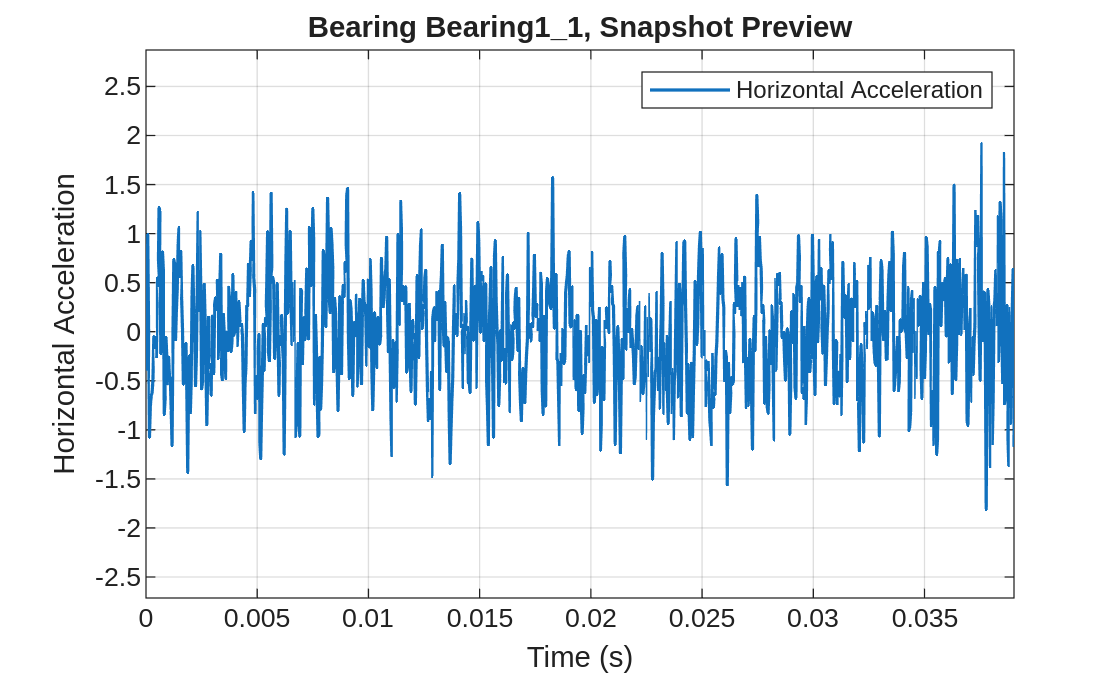

% Logical index for first snapshot
idx = firstMember.SnapshotIndex == 1;

% Extract bearing label
blabel = firstMember.Label{idx};
% Extract horizontal acceleration
h_acc = firstMember.HorizontalAcceleration{idx};
% Visualize first 1000 samples, see 
previewSnapshot(sp,h_acc,1000,blabel);

## Ensemble bookeeping

We will be generating new information based on the raw signals. This information is tipically stored in new columns in the tables associated with the ensemble members. To facilitate keeping track of the new columns without having to rewrite our scripts, we provide an EnsembleFactory class.

## Ensemble processing

SRFRs tolbox defines auxiliary classes to process our ensemble in this section we explain those classes and how to use them.

### EnsembleProcessor class

[EnsembleProcessor](matlab:open('./api/EnsembleProcessor.mlx')) is an abstract base class defining the interface and core functionality for processing ensembles of data using parallel execution, Figure 2 shows the Properties and methods. 

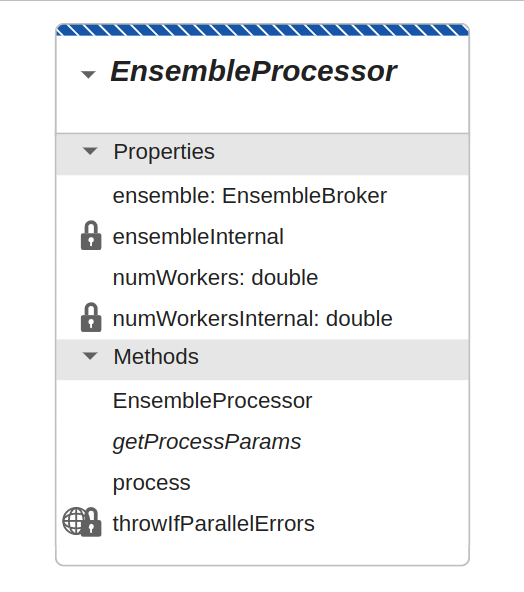

**Figure 2**. EnsembleProcessor class.

The two important properties of this class are `ensemble` and `numWorkers`.

- `ensemble` is an object of class `EnsembleBroker`.

- `numWorkers` specifies the number of concurrent processes to instantiate.

Since this class is abstract, it cannot be instantiated directly. Instead, it must be inherited, and all abstract members must be implemented. The advantage of this design is that worker handling and message logging are already implemented and tested in this class. For further details, please refer to the [`EnsembleProcessor`](matlab:open('./api/EnsembleProcessor.mlx')) class documentation.

We provide two instances of this class to illustrate its usage and because they are required for computing condition indicators. However, the design also allows the machinery to be used for other computations.  Figure 3 shows two subclasses of `EnsembleProcessor:`  [FFTEnsembleProcessor](matlab:open('./api/FFTEnsembleProcessor.mlx')) and [SFRFsEnsembleProcessor](matlab:open('./api/SFRFsEnsembleProcessor.mlx')). These subclasses are concrete and can be instantiated.

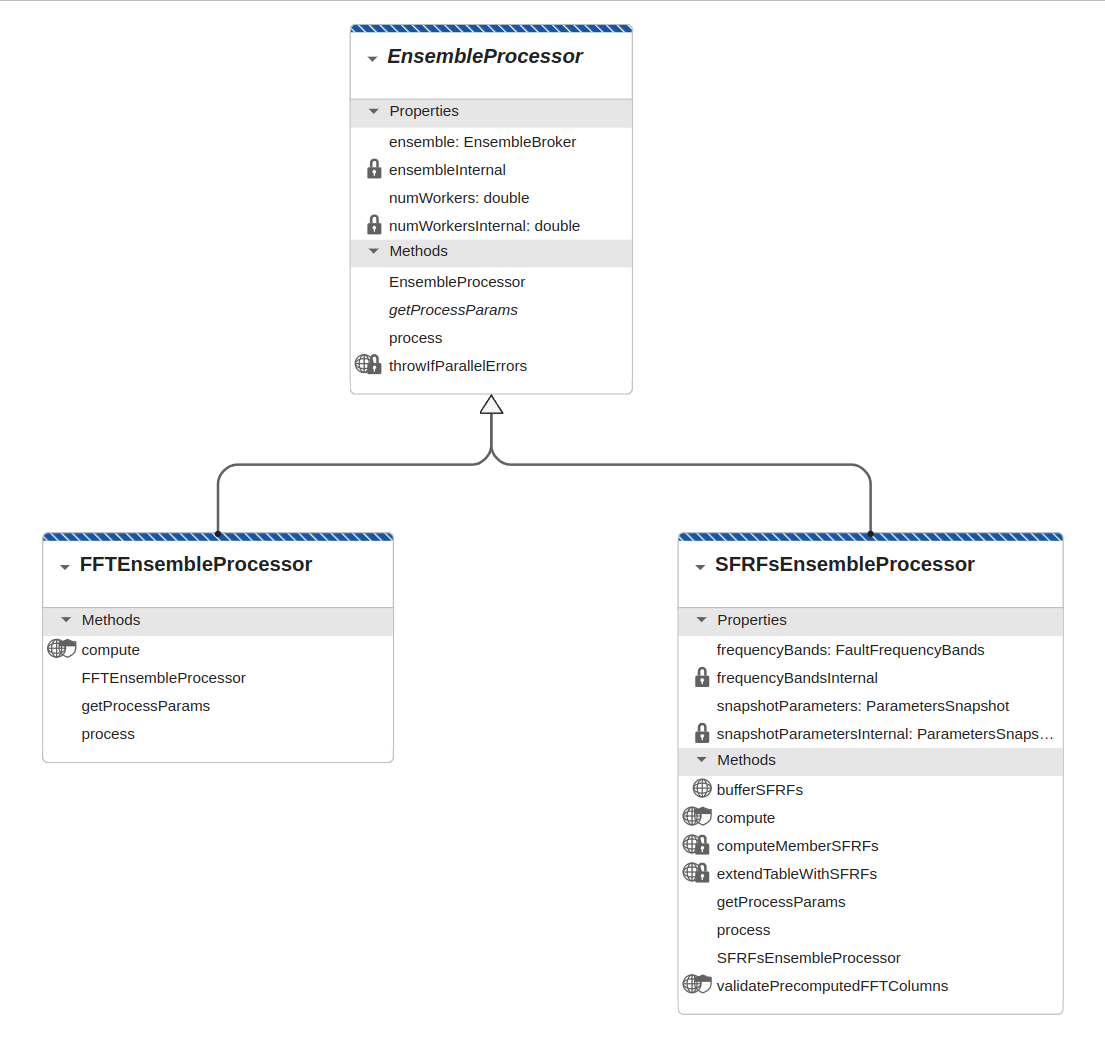

**Figure 3**. Subclasses of EnsembleProcessor. [FFTEnsembleProcessor](matlab:open('./api/FFTEnsembleProcessor.mlx')) computes the FFT of vibration signals and [SFRFsEnsembleProcessor](matlab:open('./api/FFTEnsembleProcessor.mlx')) computes the CIs using SFRFs.

### EnsembleBroker class

[EnsembleBroker](matlab:open('./api/EnsembleBroker.mlx'))  serves as the central access layer within the SFRFs toolbox, standardizing how ensemble members are discovered, loaded, saved, and interpreted while remaining fully adaptable to different data formats and organizational schemes. We don't directly pass the [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle to the processor, instead we wrap it in the broker.

% Name of the columns containing the raw signals
temporalSnapshotColumns = {...
    'HorizontalAcceleration', 'VerticalAcceleration'};

% Create broker
broker = SFRFsEnsembleBroker( ...
    'ensembleObject', ensemble, ...
    'getFilesFunction', @(obj) obj.Files, ...
    'temporalSnapshotColumns', temporalSnapshotColumns)

broker =   SFRFsEnsembleBroker with properties:

        sfrfsSuffixInternal: "_SFRFs"
                   ensemble: [1×1 fileEnsembleDatastore]
                  sortField: "SnapshotIndex"
         memberTableVarName: "ensembleMemberTable"
    temporalSnapshotColumns: {'HorizontalAcceleration'  'VerticalAcceleration'}
             spectralSuffix: "_FFT"


### FFTEnsembleProcessor class

[FFTEnsembleProcessor](matlab:open('./api/FFTEnsembleProcessor.mlx')) is a concrete subclass of [`EnsembleProcessor`](matlab:open('./api/EnsembleProcessor.mlx')) for parallel computation of FFTs on ensemble member signals. We will use it to compute the FFT of all vibration signals. In order to perform the transformation we need to create an [EnsembleBroker](matlab:open('./api/EnsembleBroker.mlx')) instance that contains the configuration for the mappings and wraps the [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle. We can find further details in [FFTEnsembleProcessor](matlab:open('./api/FFTEnsembleProcessor.mlx')).

% Creation of the processor
processor = FFTEnsembleProcessor(...
    numWorkers = 4, ... % modify according to your needs
    ensemble = broker);

% Execution of the parallel computation
% It will take a while, you can monitor activity of workers
% Using the Logger (See SFRFsLogger live script)
processor.process();

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


### Extracting the result

We will obtain the first member from the [fileEnsembleDatastore](https://www.mathworks.com/help/predmaint/ref/fileensembledatastore.html) handle to visualize the result.

% we recover first member of the ensemble in the broker
broker = processor.ensemble;
ensemble = broker.ensemble;
disp(ensemble);

  fileEnsembleDatastore with properties:

                 ReadFcn: @readMember
        WriteToMemberFcn: @writeMember
           DataVariables: [2×1 string]
    IndependentVariables: [2×1 string]
      ConditionVariables: [3×1 string]
       SelectedVariables: [7×1 string]
                ReadSize: 1
              NumMembers: 15
          LastMemberRead: "/home/stan/tmp/tocomputefft/select/Bearing1_1.mat"
                   Files: [15×1 string]



First thing to note is that the current selected variables don't include the new computed columns.

% Display selecte variables
disp(ensemble.SelectedVariables)

    "Label"
    "SnapshotIndex"
    "Speed"
    "Load"
    "Lifetime"
    "HorizontalAcceleration"
    "VerticalAcceleration"



Nor do the data variables.

% Display data variables
disp(ensemble.DataVariables)

    "HorizontalAcceleration"
    "VerticalAcceleration"



We can obtain the new columns as follows:

FFTCols = string(...
    cellfun(@(c) broker.mapToSpectralColumn(c), ...
        temporalSnapshotColumns, ...
        'UniformOutput', false)).';
disp(FFTCols);

    "HorizontalAcceleration_FFT"
    "VerticalAcceleration_FFT"



We need to update the configuration of the ensemble to take into account the new columns. The class `EnsembleDatastoreRegistry` provides with support to keep track of changes in the ensembles. For more details see: [`EnsembleDatastoreRegistry`](matlab:open('./api/EnsembleDatastoreRegistry.mlx')). We will first register our ensemble in the registry and then reconfigure it.

% Registering XJTU-SY dataset in the registry 
EnsembleDatastoreRegistry.addEnsemble( ...
    name="XJTU-SY", datastore=ensemble);

% Get fileEnsembleDatastore handle
ds = EnsembleDatastoreRegistry.getEnsemble("XJTU-SY");

% Reconfigure the ensemble to include new columns (idempotent)
ds = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
    name = "XJTU-SY", ...
    DataVariables = unique([ds.DataVariables(:);    FFTCols(:)], ...
    "stable"), ...
    SelectedVariables = unique([ds.SelectedVariables(:); FFTCols(:)], ...
    "stable"));
disp(ds)

  fileEnsembleDatastore with properties:

                 ReadFcn: @readMember
        WriteToMemberFcn: @writeMember
           DataVariables: [4×1 string]
    IndependentVariables: [2×1 string]
      ConditionVariables: [3×1 string]
       SelectedVariables: [9×1 string]
                ReadSize: 1
              NumMembers: 15
          LastMemberRead: [0×0 string]
                   Files: [15×1 string]



We can inspect the computed columns are there and obtain the data for one bearing.

firstMember = read(ensemble);
summary(firstMember);


firstMember: 123×9 table

Variables:

    Label: string
    SnapshotIndex: double
    HorizontalAcceleration: cell
    VerticalAcceleration: cell
    HorizontalAcceleration_FFT: cell
    VerticalAcceleration_FFT: cell
    Speed: double
    Load: double
    Lifetime: double

Statistics for applicable variables:

                                  NumMissing      Min      Median       Max       Mean          Std    

    Label                             0                                                                
    SnapshotIndex                     0             1         62        123         62        35.6511  
    HorizontalAcceleration            0           

### Visualizing the spectra

As a sanity check, we can extract the spectra of the first snapshot and visualize it.

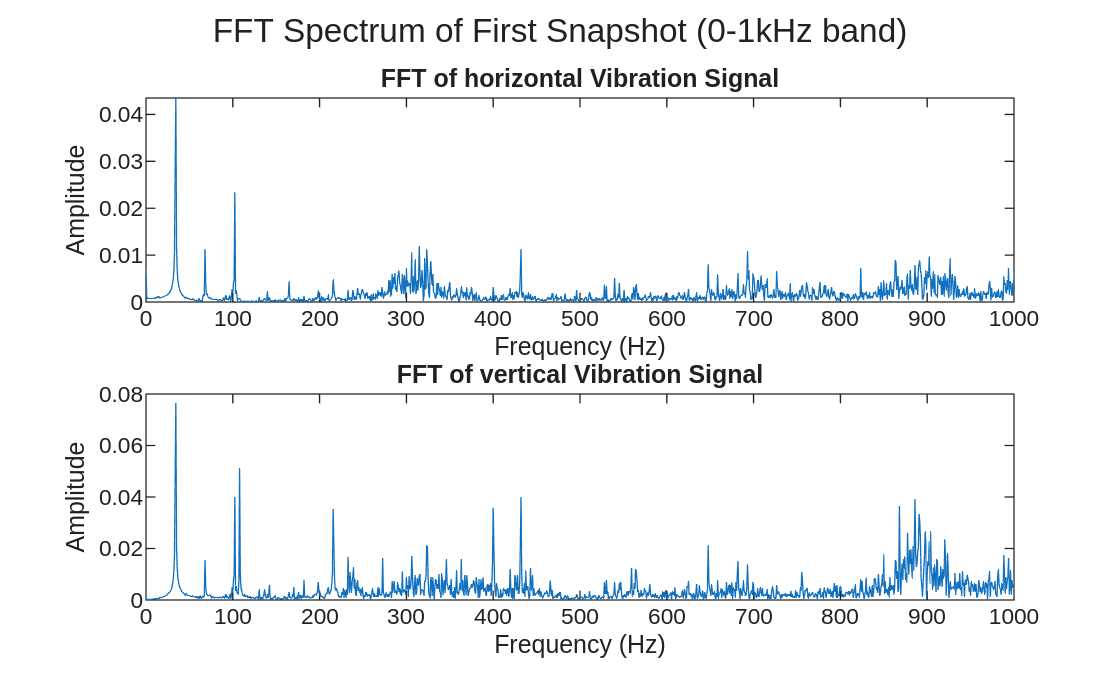

% Logical index for first snapshot
idx = firstMember.SnapshotIndex == 1;
% Extract horizontal acceleration
h_spec = firstMember.HorizontalAcceleration_FFT{idx};
v_spec = firstMember.VerticalAcceleration_FFT{idx};

h_spec = h_spec / length(h_spec);
v_spec = v_spec / length(v_spec);

plotSpectra(sp.getFrequencyDomain(),abs(h_spec),abs(v_spec),1000,...
    'FFT Spectrum of First Snapshot');

## SFRFsEnsembleProcessor class

The class [SFRFsEnsembleProcessor](matlab:open('./api/SFRFsEnsembleProcessor.mlx')) can compute the SFRFs for a given ensemble. To be able to use it we need to instantiate several objects first, for a complete description see [SFRFsEnsembleProcessor](matlab:open('./api/SFRFsEnsembleProcessor.mlx')).

### Creation of SFRFs bearing parameters

% Create SFRFs parameters for bearing faults
% SFRFs order
order = 0;
% number of sidebands
numSidebands = 2;
% number of harmonics
numHarmonics = 10;
% center bandwith (Hz)
centerBandwith = 4;
% center sigma rule
centerSigmaRule = 2;
% center shape parameters
sigmaCenter = [centerBandwith,centerSigmaRule];
% center bandwith (Hz)
surroundBandwith = 3*centerBandwith;
% center sigma rule
surroundSigmaRule = 2;
% center shape parameters
sigmaSurround = [surroundBandwith,surroundSigmaRule];
% inhibition factor
inhibitionFactor = 1/3;
% use static method to define the SFRFs parameters
sfrfsParams = SFRFsParameters.createSFRFsParameters(...
    order=order, ...
    numHarmonics=numHarmonics, ...
    numSidebands=numSidebands, ...
    sigmaCenter=sigmaCenter, ...
    sigmaSurround=sigmaSurround, ...
    inhibitionFactor=inhibitionFactor);

% Same parameters for all bearing fault types
sbp = SFRFsParametersRollingBearings( ...
      SameForAllFaultTypes = sfrfsParams);
disp(sbp);

  SFRFsParametersRollingBearings with properties:

                       outerRace: [1×1 struct]
                       innerRace: [1×1 struct]
                            ball: [1×1 struct]
                            cage: [1×1 struct]
      OUTER_RACE_FAULT_TYPE_NAME: 'outerRace'
      INNER_RACE_FAULT_TYPE_NAME: 'innerRace'
            BALL_FAULT_TYPE_NAME: 'ball'
            CAGE_FAULT_TYPE_NAME: 'cage'
                      faultTypes: {'outerRace'  'innerRace'  'ball'  'cage'}
                ORDER_PARAM_NAME: 'order'
        NUM_SIDEBANDS_PARAM_NAME: 'numSidebands'
        NUM_HARMONICS_PARAM_NAME: 'numHarmonics'
         SIGMA_CENTER_PARAM_NAME: 'sigmaCenter'
       SIGMA_SURROUND_PARAM_NAME: 'sigmaSurround'
    INHIBITION_FACTOR_PARAM_NAME: 'inhibitionFactor'
                      sfrfFields: {'order'  'numSidebands'  'numHarmonics'  'sigmaCenter'  'sigmaSurround'  'inhibitionFactor'}



### SFRFs broker creation

The specialized ensemble broker for SFRFs calculation is [SFRFsEnsembleBroker](matlab:open('./SFRFsEnsembleBroker.mlx')) (follow the link for a detailed description). 

% Recover the fileEnsembleDatastore
ds = EnsembleDatastoreRegistry.getEnsemble("XJTU-SY");
% Initialize the ensemble broker with the obtained ensemble
broker = SFRFsEnsembleBroker( ...
    EnsembleObject=ds, ...
    GetFilesFunction=@(obj) obj.Files, ...
    TemporalSnapshotColumns=temporalSnapshotColumns)

broker =   SFRFsEnsembleBroker with properties:

        sfrfsSuffixInternal: "_SFRFs"
                   ensemble: [1×1 fileEnsembleDatastore]
                  sortField: "SnapshotIndex"
         memberTableVarName: "ensembleMemberTable"
    temporalSnapshotColumns: {'HorizontalAcceleration'  'VerticalAcceleration'}
             spectralSuffix: "_FFT"


### Bearing fault characteristic frequencies

We already computed objects for representing operating conditions, bearing geometry, and signal snapshot definition, we need to compute now the fault characteristic frequencies. To compute the fault frequency bands we delegate the calculation to the class [BearingFrequencyBands](matlab:open('./BearingFrequencyBands.mlx')) (follow the link for more details).

% Create monitoring frequency bands for the bearings
bearingFrequencyBands = BearingFrequencyBands( ...
    bearingParams = bp, ...
    sfrfsParams = sbp, ...
    operatingConditions = oc)

bearingFrequencyBands =   BearingFrequencyBands with properties:

            bearingParams: [1×1 ParametersRollingBearings]
                BPFO_CODE: 'Fo'
                BPFI_CODE: 'Fi'
                 BSF_CODE: 'Fb'
                 FTF_CODE: 'Fc'
                  FR_CODE: 'Fr'
      faultFrequencyCodes: {'Fo'  'Fi'  'Fb'  'Fc'}
    faultTypeDescriptions: [4×1 containers.Map]
          faultTypeGroups: [4×1 containers.Map]
     faultGroupToTypeName: [4×1 containers.Map]
              sfrfsParams: [1×1 SFRFsParametersRollingBearings]
      operatingConditions: [1×1 OperatingConditions]
               bandsTable: [0×0 table]


### SFRFs computation

% Creation of the processor
% The required memory depends on the number of processes
processor = SFRFsEnsembleProcessor(...
    numWorkers = 5, ... % you might need to scale down this parameter
    ensemble = broker, ...
    frequencyBands = bearingFrequencyBands, ...
    snapshotParameters = sp);

% Parallel processing of the members
% Computation will take a while
processor.process();

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 5 workers.


% Obtain name of SFRF-computed columns
SFRFsCols = string( ...
    cellfun(@(c) broker.mapToSFRFColumn(c), ...
        temporalSnapshotColumns, ...
        'UniformOutput', false)).';

% Get XJTU-SY datastore
ds = EnsembleDatastoreRegistry.getEnsemble("XJTU-SY");

% Only add missing SFRF variables
newVars = setdiff(SFRFsCols(:), ds.DataVariables(:), 'stable');

ds = EnsembleDatastoreRegistry.reconfigureEnsemble( ...
        name = "XJTU-SY", ...
        DataVariables = [ds.DataVariables(:); newVars(:)], ...
        SelectedVariables = [ds.SelectedVariables(:); newVars(:)]);

% Sanity check: read and summarize transformed data
firstMember = read(ds);
summary(firstMember);


firstMember: 123×2 table

Variables:

    SnapshotIndex: double
    HorizontalAcceleration_SFRFs: cell

Statistics for applicable variables:

                                    NumMissing     Min     Median      Max       Mean         Std    

    SnapshotIndex                       0           1        62        123        62        35.6511  
    HorizontalAcceleration_SFRFs        0                                                            



### Visualizing SFRFs

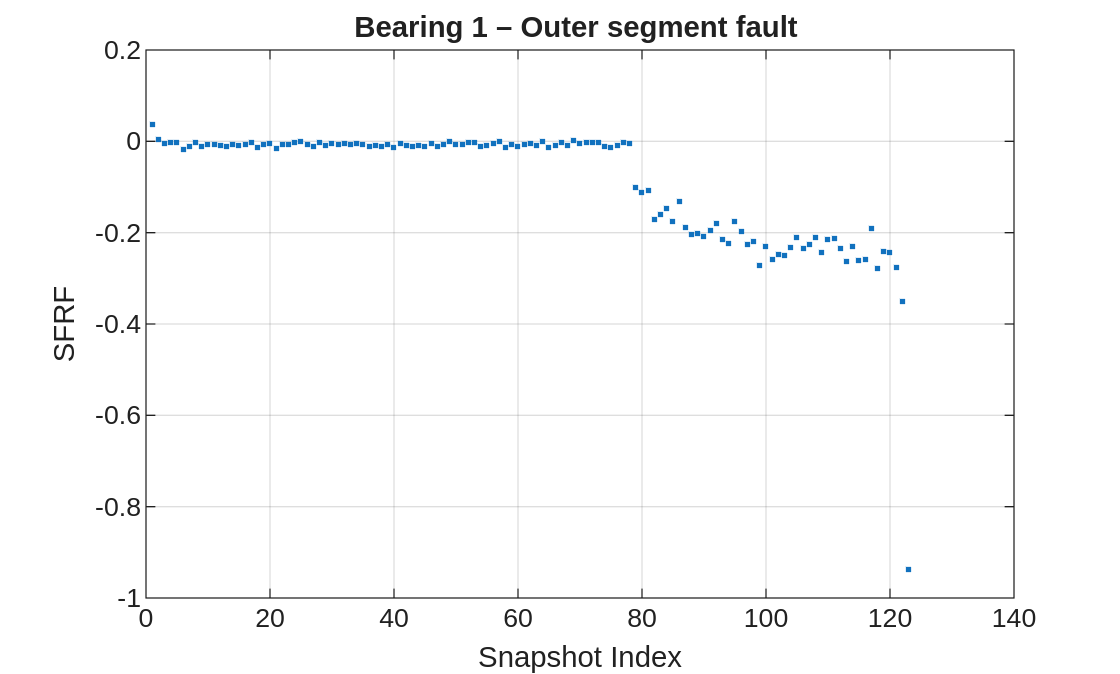

% We can visualize the condition indicator for BPFO
% with our empirical selection of parameters
plotSFRFsComponentForBearing( ...
    ensembleName = "XJTU-SY", ...
    sfrfColumn   = "HorizontalAcceleration_SFRFs", ...
    faultType    = "Outer segment fault", ...
    component    = 1, ...
    bearingIndex = 1);

## Auxiliary functions

### Ploting time snapshots

function fig = previewSnapshot(paramsSnapshot, accelSignal, nView, label)
% previewSnapshot Visualizes a snapshot of an acceleration signal
%   Plots the first N samples, using the time axis from paramsSnapshot.
%   Optionally adds a bearing or signal label to the title.
%
% Example:
%   previewSnapshot(params, h_acc, 1000, 'Label', 'Bearing_1_1')

    arguments
        paramsSnapshot (1,1) ParametersSnapshot
        accelSignal (:,1) double {mustBeFinite}
        nView (1,1) double {mustBeInteger, mustBePositive}
        label string = ""
    end

    t = paramsSnapshot.getTimeAxis();
    nView = min(nView, length(accelSignal));

    fig = plot(t(1:nView), accelSignal(1:nView), 'LineWidth', 1.2);

    xlabel('Time (s)');
    ylabel('Horizontal Acceleration');
    if strlength(label) > 0
        title(sprintf('Bearing %s, Snapshot Preview', label), ...
            'Interpreter', 'none');
    else
        title('Snapshot Preview', 'Interpreter', 'none');
    end
    grid on;
    legend('Horizontal Acceleration');
    xlim([t(1), t(nView)]);
    ylim(1.5 * [min(accelSignal(1:nView)), max(accelSignal(1:nView))]);
end


### Ploting horizontal and vertical spectra

function fig = plotSpectra(freqAxis, h_spec, v_spec, nSamples, baseTitle)
% plotSpectra  Plot horizontal and vertical FFT spectra with band in title.
%
% Usage:
%   fig = plotSpectra(freqAxis, h_spec, v_spec, nSamples, baseTitle)
%
% Inputs:
%   freqAxis  - numeric vector of frequency values (Hz)
%   h_spec    - horizontal spectrum (complex or real magnitudes)
%   v_spec    - vertical spectrum (complex or real magnitudes)
%   nSamples  - upper frequency limit to display (scalar, Hz)
%   baseTitle - base title string (char or string). Optional.
%
% Output:
%   fig - figure handle

    arguments
        freqAxis (1,:) {mustBeNumeric}
        h_spec (1,:) {mustBeNumeric}
        v_spec (1,:) {mustBeNumeric}
        nSamples (1,1) {mustBeNumeric, mustBePositive}
        baseTitle (1,:) char = "FFT Spectrum"
    end
    
    % Validate that freqAxis length exactly matches both spectra
    lenF = numel(freqAxis);
    if lenF ~= numel(h_spec) || lenF ~= numel(v_spec)
        error('freqAxis must have the same length as h_spec and v_spec.');
    end
    
    % Build title with band info (display kHz when appropriate)
    if nSamples >= 1000
        bandStr = sprintf('0-%.0fkHz band', nSamples/1000);
    else
        bandStr = sprintf('0-%dHz band', nSamples);
    end
    fullTitle = sprintf('%s (%s)', string(baseTitle), bandStr);
    
    % Create figure and plots
    fig = figure;
    
    subplot(2,1,1);
    plot(freqAxis(1:length(h_spec)), abs(h_spec));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    title('FFT of horizontal Vibration Signal');
    xlim([0, nSamples]);
    
    subplot(2,1,2);
    plot(freqAxis(1:length(v_spec)), abs(v_spec));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    title('FFT of vertical Vibration Signal');
    xlim([0, nSamples]);
    
    sgtitle(fullTitle);

end

### Ploting SFRFs

function fig = plotSFRFsComponentForBearing(args)
    arguments
        args.ensembleName   (1,1) string
        args.sfrfColumn      (1,1) string
        args.faultType        (1,1) string
        args.component        (1,1) double {mustBePositive,mustBeInteger} = 1
        args.bearingIndex      (1,1) double {mustBePositive,mustBeInteger} = 1
    end


    % Retrieve ensemble
    ds = EnsembleDatastoreRegistry.getEnsemble(args.ensembleName);

    % Only load what is needed
    ds.SelectedVariables = ["SnapshotIndex", args.sfrfColumn];

    reset(ds)

    % Jump to the requested bearing (member)
    for k = 1:args.bearingIndex
        if ~hasdata(ds)
            error("Bearing index exceeds available members.");
        end
        data = read(ds);
    end

    % Extract SnapshotIndex
    x = data.SnapshotIndex;

    % Extract SFRFs and select component
    y_raw = data.(args.sfrfColumn);

    if iscell(y_raw)
        y_raw = cell2mat(y_raw);
    end

    % First component across all snapshots
    y = y_raw(:, args.component);

    % Plot
    fig = figure;
    plot(x, y, '.');
    xlabel('Snapshot Index')
    ylabel(sprintf('SFRF'))
    title(sprintf('Bearing %d – %s ', ...
    args.bearingIndex, args.faultType))
    grid on
end


## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).

- [2] Biao Wang, Yaguo Lei, Naipeng Li, Ningbo Li, “A Hybrid Prognostics Approach for Estimating Remaining Useful Life of Rolling Element Bearings”, IEEE Transactions on Reliability, pp. 1-12, 2018. [DOI: 10.1109/TR.2018.2882682](https://doi.org/10.1109/TR.2018.2882682).